handle = load("initial_data\initial_handle.mat");
seat = load("initial_data\initial_seat.mat");

range = timerange('29-Nov-2022 16:50:17.905','29-Nov-2022 16:50:56.000','closed');
handle.Acceleration = handle.Acceleration(range, :);
handle.Orientation = handle.Orientation(range, :);
seat.Acceleration = seat.Acceleration(range, :);
seat.Orientation = seat.Orientation(range, :);

T1 = '16:50:17.905';
T2 = '16:50:39.019';
t1 = datevec(T1,'HH:MM:SS.FFF');
t2 = datevec(T2,'HH:MM:SS.FFF');
elapsed = etime(t2, t1);
slope = (264.677 - 2.4685)/elapsed;
x_int = 2.4685;

slope_handle = (-409.212 + 137.799)/(9.558 - 2.462);

handle.Velocity = timetable(handle.Acceleration.Timestamp, cumtrapz(handle.Acceleration.X), cumtrapz(handle.Acceleration.Y), cumtrapz(handle.Acceleration.Z), 'VariableNames',{'X','Y','Z'});

handle.Position = timetable(handle.Velocity.Time, cumtrapz(handle.Velocity.X), cumtrapz(handle.Velocity.Y), cumtrapz(handle.Velocity.Z), 'VariableNames',{'X','Y','Z'});

seat.Velocity = timetable(seat.Acceleration.Timestamp, cumtrapz(seat.Acceleration.X), cumtrapz(seat.Acceleration.Y), cumtrapz(seat.Acceleration.Z), 'VariableNames',{'X','Y','Z'});

seat.Position = timetable(seat.Velocity.Time, cumtrapz(seat.Velocity.X), cumtrapz(seat.Velocity.Y), cumtrapz(seat.Velocity.Z), 'VariableNames',{'X','Y','Z'});

velocity_sync = synchronize(handle.Velocity, seat.Velocity, 'union', 'linear');

normal_time = velocity_sync.Time.Second - velocity_sync.Time.Second(1,:);

normal_seat = velocity_sync.Y_2 - (slope*normal_time + x_int);

normal_handle = velocity_sync.X_1 - slope_handle*normal_time;

velo_normal = [normal_time normal_seat normal_handle]

velo_normal =          0   -2.4685    0.3189
    0.0070   -2.4826    0.2677
    0.0180   -2.5048    0.1874
    0.0270   -2.5277    0.1217
    0.0360   -2.5507   -0.0839
    0.0470   -2.5758   -0.3353
    0.0540   -2.5918   -0.5201
    0.0670   -2.6180   -0.8633
    0.0720   -2.6281   -0.9597
    0.0870   -2.6486   -1.2490


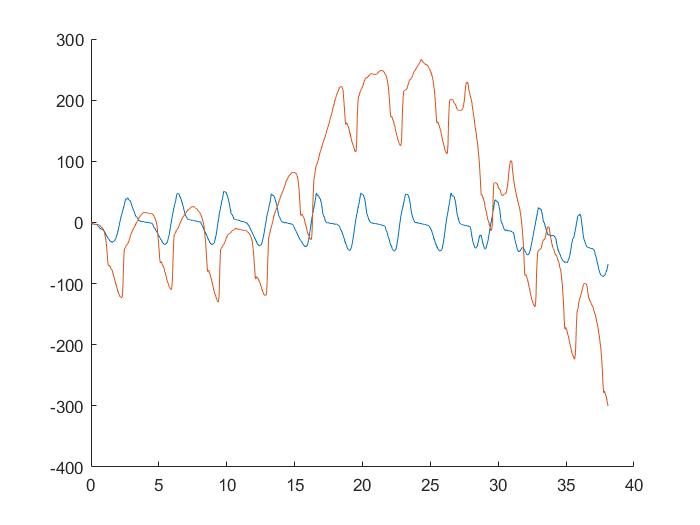



figure(2);
hold on;
plot(velo_normal(:,1), velo_normal(:,2))
plot(velo_normal(:,1), velo_normal(:,3))
hold off;


% stackedplot(handle.Acceleration)
% stackedplot(handle.Velocity)
% stackedplot(handle.Position)
% 
% stackedplot(seat.Acceleration)
% stackedplot(seat.Velocity)
% stackedplot(seat.Position)